# Sampling Theory

## For a sampled signal, $x_s \left\lbrack n\right\rbrack =x\left({\mathrm{nT}}_s \right)$ its DTFT is $X_S \left(f\right)=\frac{1}{T}\sum_{k=-\infty }^{\infty } X\left(f+k\right)$

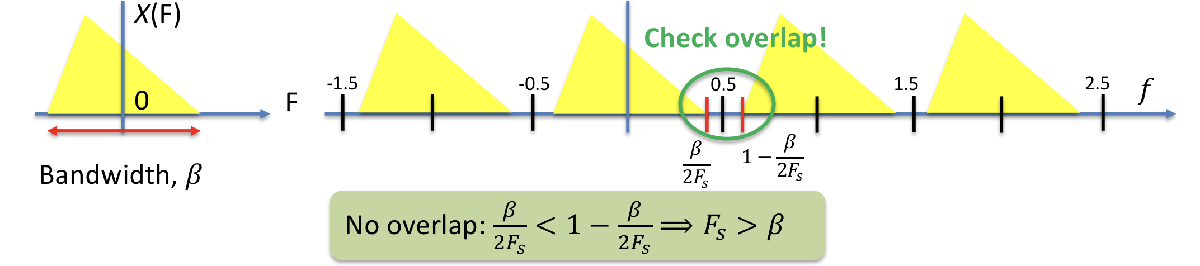

syms x; Fs = 20.5; %According to the sampling theory signal can be fully retreived when Fs > 2*f(original signal's freq) 
t = 0:1/Fs:100*(1/Fs);
Random = sin(2*pi*10*t);
a = fft(Random)

a =   -0.4753 + 0.0000i  -0.4753 - 0.0155i  -0.4753 - 0.0310i  -0.4752 - 0.0466i  -0.4750 - 0.0622i  -0.4748 - 0.0780i  -0.4746 - 0.0939i  -0.4743 - 0.1101i  -0.4740 - 0.1264i  -0.4736 - 0.1430i  -0.4731 - 0.1599i  -0.4726 - 0.1772i  -0.4721 - 0.1948i  -0.4714 - 0.2129i  -0.4707 - 0.2315i  -0.4699 - 0.2506i  -0.4690 - 0.2704i  -0.4680 - 0.2908i  -0.4669 - 0.3120i  -0.4657 - 0.3340i  -0.4643 - 0.3570i  -0.4628 - 0.3810i  -0.4611 - 0.4062i  -0.4592 - 0.4327i  -0.4570 - 0.4608i  -0.4546 - 0.4905i  -0.4518 - 0.5220i  -0.4487 - 0.5558i  -0.4451 - 0.5920i  -0.4410 - 0.6310i  -0.4363 - 0.6732i  -0.4308 - 0.7192i  -0.4243 - 0.7695i  -0.4167 - 0.8250i  -0.4077 - 0.8867i  -0.3968 - 0.9557i  -0.3836 - 1.0336i  -0.3672 - 1.1224i  -0.3467 - 1.2250i  -0.3206 - 1.3449i  -0.2865 - 1.4876i  -0.2407 - 1.6604i  -0.1775 - 1.8750i  -0.0863 - 2.1494i   0.0523 - 2.5146i   0.2786 - 3.0283i   0.6886 - 3.8127i   1.5667 - 5.1893i   4.1735 - 8.4220i  29.6237 -32.6747i


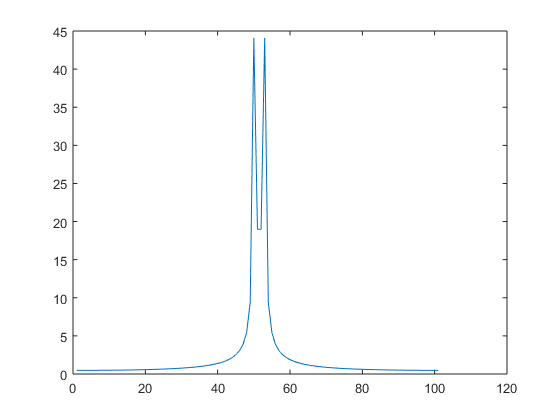

plot(abs(a))

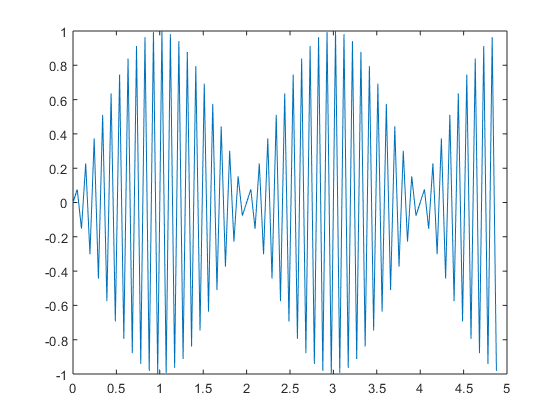

Random_origin = sin(2*pi*10*x);
plot(t,Random)% The graph may not look like it recovred everything but !! fft shows that it retreieved the signal perfectly !!

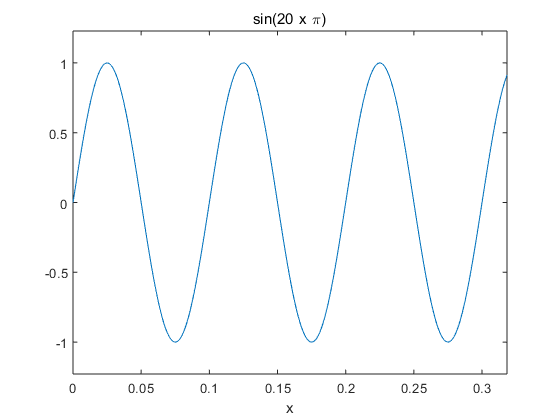

ezplot(Random_origin,[0 1/(pi)])